% Code modified from Mulhall, E.M., et al: https://doi.org/10.1038/s41586-023-06427-4to analyze triple-labeled PIEZO1 molecules from Abberior Instruments 3D MINFLUX localizations
% Modified by Chung Yu Chan
% cluster_data.m and dependencies written by Pape, J.K., et al: https://doi.org/10.1073/pnas.2009364117

% Instructions:
% First, export valid final localizations from the MINFLUX Imspector interface as a .mat file
% Import the .mat file into the current path
% If necessary, determine proper Z-filtering thresholds from examining localizations in Paraview or Matlab

% Results:
% The final identified molecules will be in the output table 'Results'

%Path to files
%Path = '/Users/path/';

% before starting, add cluster_data.m and dependencies to path

close all
clear
clc

## Load localization data

% load .mat file
mfx_data = '241211-233205_minflux.mat'

mfx_data = '241211-233205_minflux.mat'

load(mfx_data);
% set number format (optional)
%format shortE

## Filter localization data

% isolate localization and parameter arrays

% localizations
itr_loc = itr.loc;
% counts at offset
itr_eco = itr.eco;
% counts at center position
itr_ecc = itr.ecc;
% center frequency ratio
itr_cfr = itr.cfr;
% frequency at offset
itr_efo = itr.efo;

% define x,y,z coordinates for each localization and link the trace ID
x = itr_loc(:,10,1);
y = itr_loc(:,10,2);
z = itr_loc(:,10,3);
xyz = [x y z];
% Convert tid into double for import
tid = double(tid)';
traces = [x(:,1),y(:,1),z(:,1),tid(:,1)];

% input Z-filt threshold if required
%z_threshold = 0e-07

% Set standard deviation threshold per trace for each dimension (default = 10 nm)
stdev_trace_threshold = 10e-09

stdev_trace_threshold = 1.0000e-08


% Set # localizations per trace threshold (defalut > 3)
loc_per_trace_threshold = 3

loc_per_trace_threshold = 3

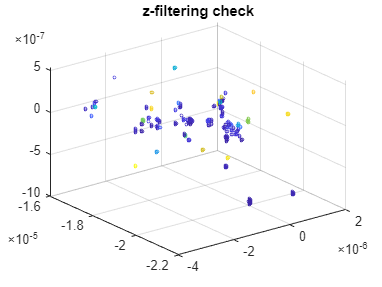


% filter #1: Z threshold
traces_filt = traces;
% output traces greater than Z-threshold
%traces_filt(traces_filt(:, 3) < z_threshold, :)= [];
% output traces less than Z-threshold
%traces_filt(traces_filt(:, 3) > z_threshold, :)= [];

% Filter #2: standard deviation per trace in each dimension
[uv_tid, ~, id_tid] = unique(traces_filt(:,4));
stdev_trace_x = [accumarray(id_tid,traces_filt(:,1),[],@std)];
traces_filt = traces_filt(ismember(traces_filt(:,4), uv_tid(stdev_trace_x < stdev_trace_threshold)),:);
% 
[uv_tid, ~, id_tid] = unique(traces_filt(:,4));
stdev_trace_y = [accumarray(id_tid,traces_filt(:,2),[],@std)];
traces_filt = traces_filt(ismember(traces_filt(:,4), uv_tid(stdev_trace_y < stdev_trace_threshold)),:);
% 
[uv_tid, ~, id_tid] = unique(traces_filt(:,4));
stdev_trace_z = [accumarray(id_tid,traces_filt(:,3),[],@std)];
traces_filt = traces_filt(ismember(traces_filt(:,4), uv_tid(stdev_trace_z < stdev_trace_threshold)),:);
 
% Filter #3: localizations per trace
% Unique elements and locations in third column
[uv_tid, ~, id_tid] = unique(traces(:,4));
% How many of each?
n_tid = histcounts(id_tid,"BinWidth",1);
% Keep ones with more than 5.
traces_filt = traces_filt(ismember(traces_filt(:,4), uv_tid(n_tid > loc_per_trace_threshold)),:);

% Plot figure to check that Z-filtering is correct
figure
scatter3(traces_filt(:,1),traces_filt(:,2),traces_filt(:,3),5,traces_filt(:,4))
title('z-filtering check')

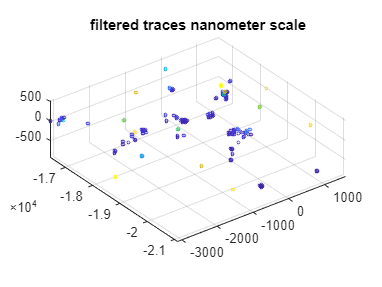


% Convert units for compatibility with later graphs
traces_filt_nano = traces_filt*10^9;

% plot the filtered data in nanometer-scale colored by tid
figure
scatter3(traces_filt_nano(:,1),traces_filt_nano(:,2),traces_filt_nano(:,3),5,traces_filt_nano(:,4))
title('filtered traces nanometer scale')
axis equal
hold on


% Put XYZ coordinates into filt_XYZ for cluster analysis 
filt_XYZ = traces_filt(:,1:3);

% Put filt_XYZ into locAll for cluster analysis
locAll = {[filt_XYZ]*10^6};

## Define dbscan and GMM parameters and load the cluster algorithm

p.cluster.algorithm = 'dbscan2';
p.cluster.dbscan2.db1_size = 10; 
p.cluster.dbscan2.db1_minPts = 2;
% db2_size is the only parameter changed, between 6-7 depending on noise
p.cluster.dbscan2.db2_size = 7;
p.cluster.dbscan2.db2_minPts = 2;
p.cluster.dbscan2.gmm_sigma = 5;
p.cluster.plot = 1;

p_save.plot_save=1;
p_save.plot_save_path = '04_Plots';
p_save.plot_save_filename_start = '';%p.cluster.algorithm;

## Perform the 2-step clustering algorithm and GMM fitting

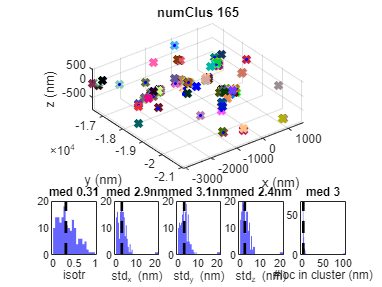

% cluster the data
clusInfo{1} = cluster_data(locAll,'params',p);

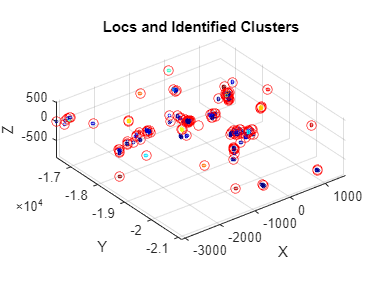

        % note that the cluster_data algorithm does not like the array size too large. In that case, the data will need to be split up between locAll{1...X}
        prmPlot.coloring = 'NN';
        clusInfo{1} = cluster_distances(clusInfo{1},0);

clust_XYZ = clusInfo{1, 1}.meanClus{1, 1};
size_clust = size(clust_XYZ);
size_clust = size_clust(:,1);
clust_index = [];
clust_index = (1:size_clust)';
clust_XYZ = [clust_XYZ clust_index];
clust_stdev = clusInfo{1, 1}.stdClus{1, 1};
% average stdev in 3 dimensions for plotting
clust_stdev_avg = ((clust_stdev(:,1) + clust_stdev(:,2) + clust_stdev(:,3))/3);

% create an XYZ + average stdev array for visualization
clust_XYZ_stdev_avg = [clust_XYZ clust_stdev_avg];

% create an XYZ + XYZ_stdev array
clust_XYZ_stdev = [clust_XYZ clust_stdev];

% plot the filtered data and the clustered data
figure
% plot cluster center positions
scatter3(clust_XYZ_stdev_avg(:,1),clust_XYZ_stdev_avg(:,2),clust_XYZ_stdev_avg(:,3),50,"red", "k")
axis equal
hold on
% plot filtered traces
scatter3(traces_filt_nano(:,1),traces_filt_nano(:,2),traces_filt_nano(:,3),5,traces_filt_nano(:,4))
colormap jet
title('Locs and Identified Clusters')
xlabel('X'); ylabel('Y'); zlabel('Z');

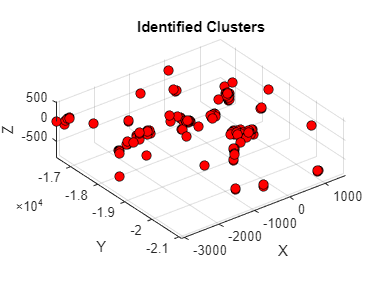


% plot cluster center positions only
figure
scatter3(clust_XYZ_stdev_avg(:,1),clust_XYZ_stdev_avg(:,2),clust_XYZ_stdev_avg(:,3),50,'red','filled','MarkerEdgeColor','k')
axis equal
title('Identified Clusters')
xlabel('X'); ylabel('Y'); zlabel('Z');

## Selecting the ROI datapoints into brushedData

% plot Identified Clusters for selectionfigure
h = scatter3(clust_XYZ_stdev_avg(:,1),clust_XYZ_stdev_avg(:,2),clust_XYZ_stdev_avg(:,3),50,'blue','filled','MarkerEdgeColor','k')

h =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: [0 0 0]
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
              XData: [-449.2358 468.6575 476.2470 141.6189 154.9876 -420.2137 -402.3690 -516.7149 -520.3130 -510.3328 -512.2667 -522.7631 -2.2990e+03 -2.2885e+03 -180.2508 -183.4385 -178.7980 -191.8443 -12.7881 -15.8026 898.8834 … ] (1×165 double)
              YData: [-1.8294e+04 -1.9122e+04 -1.9128e+04 -1.6698e+04 -1.6691e+04 -1.9569e+04 -1.9556e+04 -1.8014e+04 -1.8022e+04 -1.8004e+04 -1.8014e+04 -1.8020e+04 -1.8054e+04 -1.8061e+04 -2.0346e+04 -2.0359e+04 -2.0341e+04 … ] (1×165 double)
              ZData: [-200.9173 -369.8595 -361.8766 -216.9360 -216.7383 -238.7847 -245.2848 -214.1832 -206.1827 -208.4066 -198.7888 -191.7446 -130.6826 -138.2102 -900.8652 -906.5933 -919.5111 -869.3888 -147.9086 -146.6747 -99.1403 … ] (1×165 double)
           SizeD

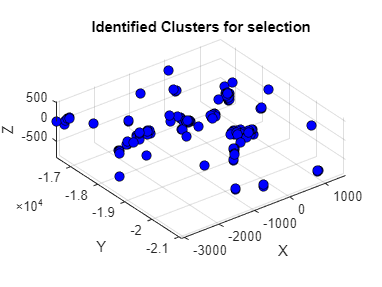

axis equal
title('Identified Clusters for selection')
xlabel('X'); ylabel('Y'); zlabel('Z');

brush on;


% Pause to allow selection (press any key to continue once selection is complete)
disp('Identified Clusters for selection, then press any key to continue.')

Identified Clusters for selection, then press any key to continue.


## Generate Identified Clusters for selected ROI

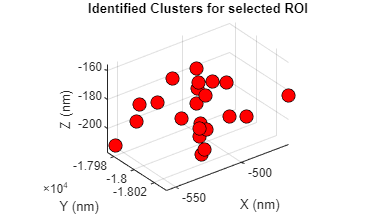

% plot Identified Clusters for selected ROI
fig = figure;
set(fig, 'Position', [100, 100, 1920, 1080]); % Set figure size for high resolution
scatter3(brushedData(:,1),brushedData(:,2),brushedData(:,3),100,'red','filled','MarkerEdgeColor','k')
axis equal

% Set manual axis limits
%xlim([9500 9800]);  % Set X-axis range
%ylim([3425 3725]);  % Set Y-axis range
%zlim([-25 275]); % Set Z-axis range
xlabel('X (nm)'); ylabel('Y (nm)'); zlabel('Z (nm)');
title('Identified Clusters for selected ROI')

## 3D volume for Identified Clusters in selected ROI

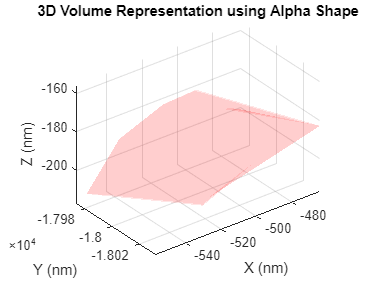

% Create an alpha shape (tunable alpha radius)
alphaRadius = 50; % Adjust this value for tighter/looser shapes
shp = alphaShape(brushedData(:,1), brushedData(:,2), brushedData(:,3), alphaRadius);

% Plot the shape
fig = figure;
h = plot(shp);
axis equal;

% Set manual axis limits
%xlim([350 650]);  % Set X-axis range
%ylim([-4500 -4200]);  % Set Y-axis range
%zlim([-300 0]); % Set Z-axis range

xlabel('X (nm)'); ylabel('Y (nm)'); zlabel('Z (nm)');
title('3D Volume Representation using Alpha Shape');
h.FaceColor = 'red'; % Set face color
h.EdgeColor = 'none'; % Remove edges for smooth appearance
alpha(0.1); % Adjust transparency

## Generate Identified Clusters + 3D volume for selected ROI

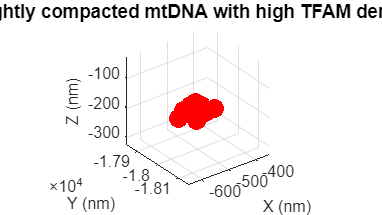

% plot Identified Clusters for selected ROI
fig = figure;
set(fig, 'Position', [100, 100, 1920, 1080]); % Set figure size for high resolution
scatter3(brushedData(:,1),brushedData(:,2),brushedData(:,3),200,'red','filled')
axis equal
hold on

% Create an alpha shape (tunable alpha radius)
alphaRadius = 50; % Adjust this value for tighter/looser shapes
shp = alphaShape(brushedData(:,1), brushedData(:,2), brushedData(:,3), alphaRadius);

% Plot the shape
h = plot(shp);
axis equal;
h.FaceColor = 'red'; % Set face color
h.EdgeColor = 'none'; % Remove edges for smooth appearance
h.FaceAlpha = 0.1; % Adjust transparency

% Set manual axis limits
xlim([-650 -350]);  % Set X-axis range
ylim([-18150 -17850]);  % Set Y-axis range
zlim([-325 -25]); % Set Z-axis range

% Change axis tick font size
ax = gca;  % Get current axis
ax.FontSize = 12;  % Change tick label font size
xlabel('X (nm)', 'FontSize',12); ylabel('Y (nm)', 'FontSize',12); zlabel('Z (nm)', 'FontSize',12);
title('Tightly compacted mtDNA with high TFAM density', 'FontSize',14)

## Convert figure into video

Set up the VideoWriter object

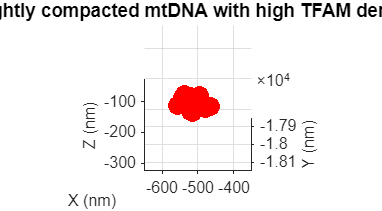

v = VideoWriter('20241211_Cell 5_high density_3D volume.mp4', 'MPEG-4');
v.FrameRate = 10;  % 10 frames per second
open(v);

% Number of frames in the video (rotate 360 degrees in steps)
numFrames = 360;

% Loop to rotate the plot and capture frames
for i = 1:numFrames
    % Set the view angle (rotate 1 degree for each frame)
    view(i, 30); % You can adjust the 30 to control the vertical angle
    
    % Capture the frame
    frame = getframe(fig);
    
    % Write the frame to the video
    writeVideo(v, frame);
end


% Close the video file
close(v);

## Create table of final results

%headers = {'X', 'Y', 'Z', 'stdev X', 'stdev Y', 'stdev Z', 'DBSCAN ID', 'Inter-blade angle', 'Inter-blade distance'};
%Results = array2table(clust_comp_DBSCAN_NN_3_sort_120_filtered, 'VariableNames', headers);

## Save work

save_name = mfx_data;
 save_name = save_name(1:end-4);

 save([save_name '_analyzed.mat'])

 disp('Processing completed!')